# Serieak eta Taylorren serieak

Tutorial honetan ikusiko dugu nola egin lan Matlab-en serieekin, bai zenbakizko serieekin bai berredura serieekin. 

clear all %Lehen zegoen guztia ezabatzeko.

## Baturak egiten

Hasteko, kontsideratu behar dugu Matlabek dela gai bektore baten elementuak batzeko. Horretarako, sum funtzioa erabili dezakegu. Adibidez:

f1= @(n) n.^2./exp(n);
format long %Dezimal guztiak ikusteko
sum(f1(1:10000))

ans =    1.992294767124988


sum(f1(1:15000))

ans =    1.992294767124988


sum(f1(1:20000))

ans =    1.992294767124988


Modu heuristiko batean ikus daiteke seriea konbergituko duela eta batura $1.9922$ inguru egongo dela

format short %Defektuzko formatuan jartzeko

## Batura partzialak bektore batean gordetzen

Bigarren aukera bat da informazioa bektore batean gordetzea batura partzialak egiten dizuena, eta gero batura partzial horiek irudikatzea. 

bat1=zeros([1 500]);

Hasteko sortuko dugu 500 tamainako bektore bat, zeroz betea. Lehen zenbakia matrizearen lerro kopurua emango dizue, eta bigarrena zutabe kopurua; hortaz, errenkada bateko matrizea sortuko du; hots, bektore bat. Zenbaki bat idatziz gero, adibididez zero(500) 500X500 tamainako matrize bat sortuko du. Azkenik, gogoratu ";" idazten dugula komando lehioa ez saturatzeko. 

bat1(1)=f1(1);

Matlabek ahalbidetzen du bektoreen gaiak aldatzea. Ez ahaztu  ";" idaztea emaitza ez agertzeko. 

for k=2:500 %for erabiltzen da agindu bat(zuk) hainbat alditan aplikatzeko. 
    bat1(k)=bat1(k-1)+f1(k);%bektorearen k. gaia k-1 batura partzial gehi k. gaia
end

Hauxe da modurik efizientena. Ere idatz daiteke bat1(k)=sum(f(1:k)), baina hori ez da efizientea, batura berdinak behin eta berriz egiten baititu, programa moteltzen. Gogoratu bektorea Workspace atalean kontsulta dezakuzuela. Azkenik, batura partzialen segida irudika ditzakegu:

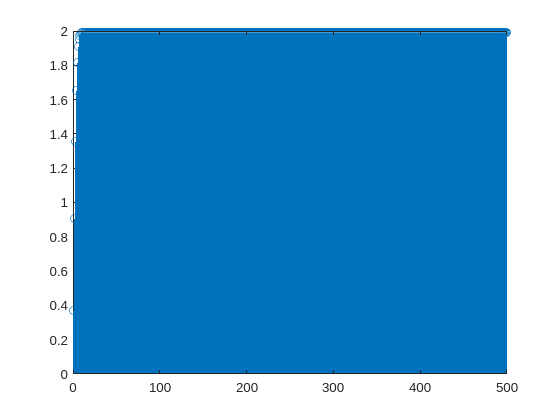

stem(bat1)

Zooma eginez modu heuristiko batean esan daiteke konbergitzen dela. Noski %100 ziurtasuna izateko, metodo matematikoa erabili behar da.

## Taylorren serieak eta irudikatzeko erak.

Orain ikusiko dugu berredura serieen batura nola irudikatu. Horretarako, irudikatuko dugu esponentzialaren eta $\frac{1}{1+x^2}$-ren berretura serieak$[-1,1]$ tartean. Zorionez, hau guztia erraz egin dezakegu existitzen baita komando bat Matlaben Taylorren segidak kalkulatzen dizkizuena (**taylor **hain zuzen ere). Horretarako aldagai sinbolikoak erabili behar dira.

syms x
p_4(x) =taylor(exp(x))

$$p\_4(x) = \frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

Hemen ez dugu @ notazioa erabili behar x aldagai sinbolikoa delako; izan ere, funtzio sinbolikoak izena(aldagaia) = aldagaia duen adierazpen bat bezala idatz daitekealdagaia sinbolikoa dela deklaratu denean. Defektuz, ezer esaten ez badiogu lehenengo aldagai sinbolikoko berredura Taylorren 5 hurbilpena kalkulatuko du. Aldiz, $n$. ordeneko Taylorren batura nahi badugu '**order**' eta $n+1$ idatzi behar dugu. 

p_10(x)= taylor(exp(x),'order',11); 

Bai, funtzio bat definitzeko orduan beste funtzio bat erabili dezakezue definizioan. Ez ahaztu 0. gaia ere gehitu kontatzen duela. Ikus dezagun zelan aproximatu duen esponentzila:

exp(1)-p_10(1)

$$ans = \frac{871799979767}{31919262358988390400}$$

Aldagai sinboliko denez Matalbek saiatzen da ahalik eta era zehatzen idazten. Hurbilpen praktiko nahi badugu nahikoa da **double** idaztea, zenbakizko balioetara pasatzera (hor, defektuz, 5 digitu erakuzten ditu):

double(exp(1)-p_10(1))

ans = 2.7313e-08

double(exp(1)-p_10(1))-2.7313e-08

ans = -3.3939e-13

Ikusten, bakarrik erakutsi dizue 5 digitu esanguratsuenak, baina Matlabek bere baitan dezimal gehiagorekin egiten du lan.

Emaitzari begiratuz, badirudi lehenenego 8 digituak lortu ditugula. Noski, horrela konprobazioak egitea oso neketsua izan daiteke; ez da workspacen bektore baten gaiak begiratzeko bezain azkar. Hoberena grafiko bat egitea da.

## Funtzioen grafikoak:

Ikus dezagun orain nola egin grafo estatiko bat. Horretarako, **fplot** erabiliko dugu; horrela irudika baitezakegu Matlaben funtzioak. Hasteko, irudika ditzagun esponentzialaren grafoa 

fplot(exp(x),[-1 1],'Linewidth',5)

**fplot**-en aurretik edo @funtzio bat ezer gabe edo funtzio sinboliko bat behar da. Funtzio sinbolikoa aldagaiarekin jarri ahal da aurretik ondo definitua ez badago, edo izenarekin bakarrik, gero ikusiko dugun bezala. Lehenengo agindua da funtzioa, bigarrena tartea da, hirugerrena autazko parametro bat eta kurben lodiera. Lodiera handitu dugu hobeto ikusteko.

title('Esponentzialaren hurbilpena Taylorren bidez') 

**title** balio du  grafoari izenburua jartzeko

legend('e^x')

Esponentziala dela adierazteko legend erabili dezakegu. Hori ondo etorriko zaigu beste kurbaz ezberdintzeko.  Jarraitzeko irudika ditzagun orain hurbilpenak:

p_1(x)= taylor(exp(x),'order',2); %lehen ordeneko hurbilpena
p_2(x)= taylor(exp(x),'order',3); %bigarren ordeneko hurbilpena
p_3(x)= taylor(exp(x),'order',4); %hirugarren ordeneko hurbilpena 
p_5(x)= taylor(exp(x),'order',6); %bostgarren ordeneko hurbilpena
p_10(x)= taylor(exp(x),'order',11);%10. ordeneko hurbilpena
hold on %Esateko Matlabi aurreko grafoa ez ezabatzeko eta hold off idatzi arte
%grafoak bata bestearen gainean irudikatzea.
fplot(p_1,[-1 1],'Displayname','p_1','Linewidth',2)

**Displayname**  balio dizue funtzio horren leienda gehitzeko, grafikoa begiratzen kurbak ezberdintzeko. $p_1$ jada definituta dagoenez, ez ba beharrezkoa (x) idaztea, nahiz eta idatz daiteke. 

fplot(p_2,[-1 1],'Displayname','p_2','Linewidth',2)
fplot(p_3,[-1 1],'Displayname','p_3','Linewidth',2)
fplot(p_5,[-1 1],'Displayname','p_5','Linewidth',2)
fplot(p_10,[-1 1],'Displayname','p_{10}','Linewidth',2)

Ikusten denez, $[-1,1]$ tartean $3$. ordeneko hurbilpena oso fidagarria da, $5$. ezberdintzeko zoom asko egin behar dugu ($4$ digitu) eta $10$. ia itsitsita dago. Noski, zenbat eta tartea gehiago handitu, orduan eta gehiago ezberdinduko dira Taylorren hurbilpenak eta esponentziala. 

Behin grafoa izanda, exporta dezagun pdf bat bezala:

Sizegcf= get(gcf, 'PaperPosition');
set(gcf, 'PaperSize', [Sizegcf(3) Sizegcf(4)]); 

Lehenengo bi agianduak balio dute grafoa tamaina handi batekin ateratzeko. Erabilgarria izan daiteke powerpoint batean jarri nahi baduzue. 

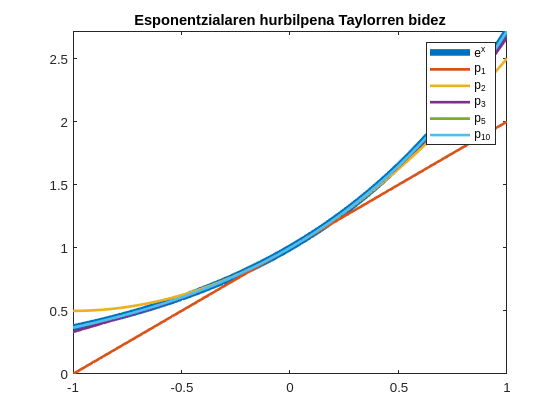

saveas(gcf, 'Taylorexp', 'pdf') %Save figure
clear x %Nahi badugu x aldagai sinbolikoa izaten uztea, horrela adierazi behar da.
hold off %Aurretik zuen grafoa ezabatzeko agindua

## $\frac{1}{1+x^2}$ funtzioa irudikatzen. 

%Egin dezagun aurrekoaren berdina $\frac{1}{1+x^2}$ funtzioarekin. 

syms x
func(x)=  1./(1+x.^2); %Hurbilduko dugun funtzioa.
fplot(func,[-1 1], 'Linewidth',5)
title('(1+x^2)^{-1} hurbilpena Taylorren bidez')
legend('(1+x^2)^{-1}')
q_2(x)= taylor(func(x),'order',3); %bigarren ordeneko hurbilpena
q_4(x)= taylor(func(x),'order',5); %laugarren ordeneko hurbilpena
q_6(x)= taylor(func(x),'order',7); %seigarren ordeneko hurbilpena 
q_10(x)= taylor(func(x),'order',11); %10. ordeneko hurbilpena
q_20(x)= taylor(func(x),'order',21);%20. ordeneko hurbilpena
hold on %Esateko Matlabi aurreko grafoa ez ezabatzeko
fplot(q_2,[-1 1],'Displayname','q_2','Linewidth',2)
fplot(q_4,[-1 1],'Displayname','q_4','Linewidth',2)
fplot(q_6,[-1 1],'Displayname','q_6','Linewidth',2)
fplot(q_10,[-1 1],'Displayname','q_{10}','Linewidth',2)
fplot(q_20,[-1 1],'Displayname','q_{20}','Linewidth',2)

Hemen hurbilpena ez da hain ona. Normala, kontsideratuz $x=-1,1$ tartaean oszilatzen duela (eta hortik kanpo dibergitu). Hori bai, zenbat eta $0$-tik  hurbilago egon, orduan eta azkarrago konbergituko du polinomioa. 

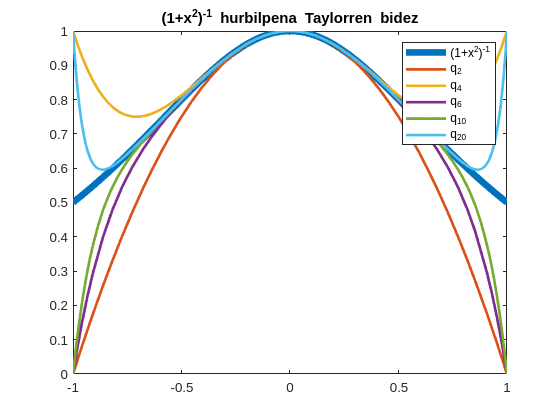

hold off